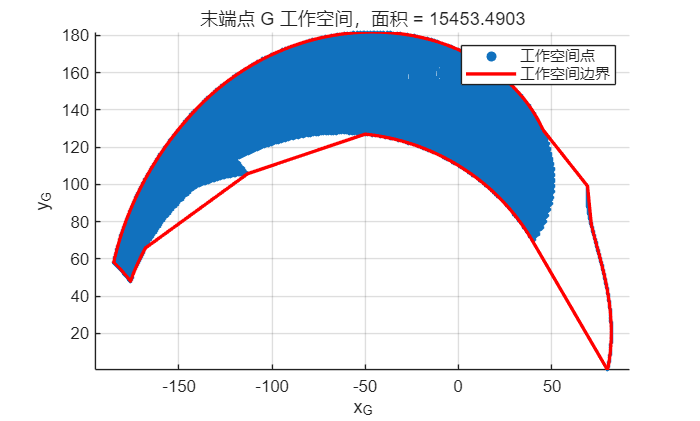

clc;
clear;
close all;
addpath('../Definition'); 
addpath('../Kinematics');
run('../Definition/set_parameter.m');

%% 输入角度范围
theta_range = [0, 180];    % deg
phi_range   = [0, 180];    % deg

%% 采样精度
n_theta = 300;
n_phi   = 300;

%% boundary 收缩因子
% shrink_factor = 1 时为凸包
% shrink_factor 越小，边界越贴合非凸工作空间
shrink_factor = 0.8;

%% 是否绘图
plot_flag = true;

%% 计算工作空间面积
[area_ws, xg, yg, xb, yb] = calcWorkspaceArea( ...
    theta_range, phi_range, params, ...
    n_theta, n_phi, shrink_factor, plot_flag);


fprintf('末端点 G 的工作空间面积为：%.6f\n', area_ws);

末端点 G 的工作空间面积为：15453.490345
